% generate figure S5
% dependence: initRSG2prior, v2struct

### set up

S=initRSG2prior;
v2struct(S); % behDir

### main loop

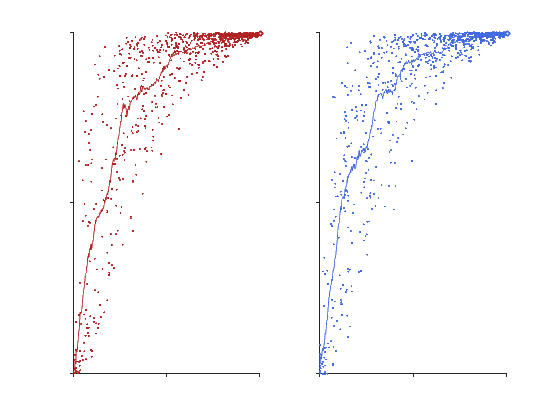

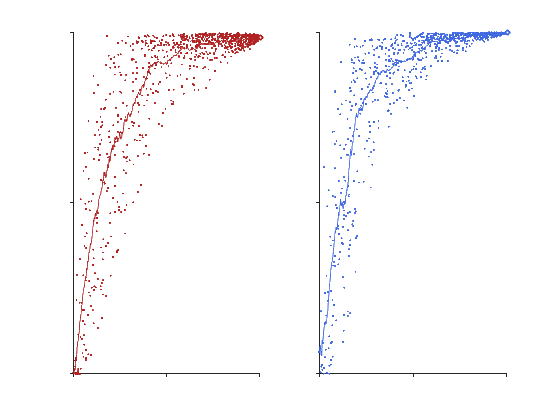

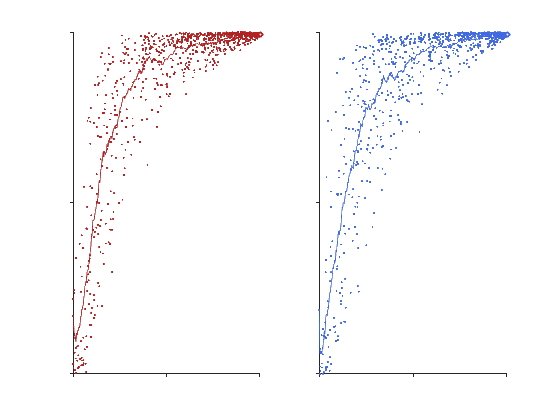

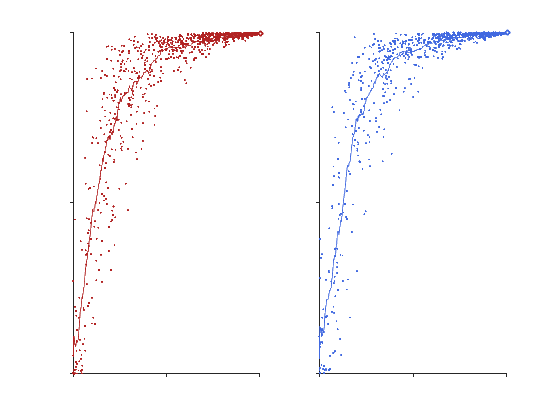

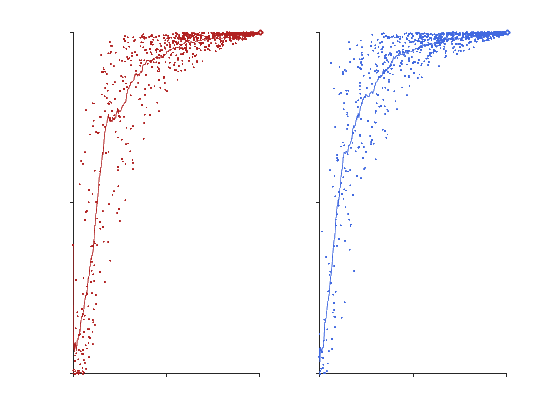

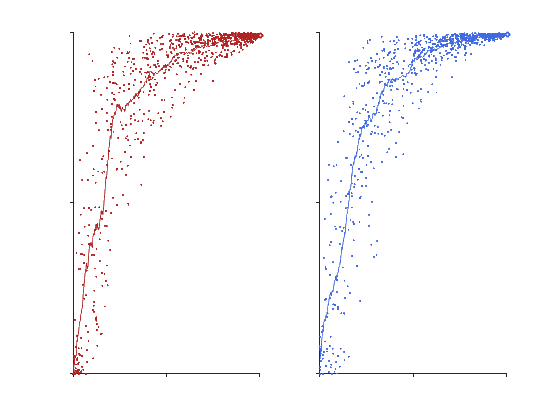

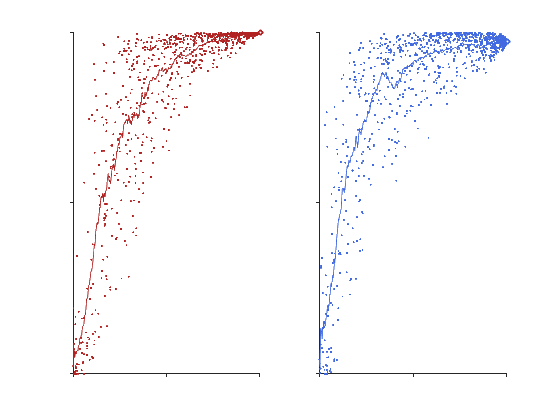

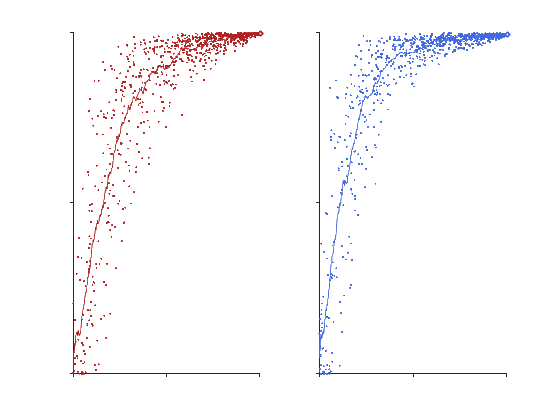

disp('==========');
disp('figS5A');
disp('==========');
plot_R2_angle(S); % figS5A

drawnow; pause(0.5);

plot_distance_go(S); % figS5B: done by Nico


function plot_distance_go(S) % figS5B

end

function plot_R2_angle(S) % figS5A

v2struct(S);
cd(psthDir);

nWin=50; % window for moving average

load('R2BLSrotation.mat'); % estR2BLSIC_fig3d
dAngleDot=cosd(dAngle);
for iDS=1:size(dAngle,1)
    %             deg2polar=@(x,iPr) deg2rad(((iPr==1)+(iPr==nPr)*(-1))*x+90); % left for short, right for long
    hFig=figure; % eye for 1st row; LeftG, LeftH, RightG, RightH
    for iPr=1:nPr
        subplot(1,nPr,iPr);
        
        tmpX=squeeze(dAngleDot(iDS,:,iPr)); % 2*(iPr-1.5)* % short in left
        tmpY=squeeze(r2(iDS,1:(end-1),iPr));
        
        % individual rand
        plot(tmpX,tmpY,'.','color',tmpCmap{iPr,1}(1,:),'markersize',msize2);ha; % individual rand
        
        % moving average
        [tmpXsort,idSort]=sort(tmpX(:));
        x2=smooth(tmpXsort(:),nWin);y2=smooth(tmpY(idSort),nWin);
        plot(x2,y2,'-','color',tmpCmap{iPr,1}(1,:),'linewidth',lw2);
        plot(1,r2(iDS,end,iPr),'o','color',cmapPr(iPr,:),'markersize',msize,'markerfacecolor','w','linewidth',lw);ha; % acutal data 0 2*(iPr-1.5)
%         plot(dAngleDot(iDS,iRandEx{iPr},iPr),r2(iDS,iRandEx{iPr},iPr),'d','color',cmapRot(iPr,:),'markersize',msize,'markerfacecolor','w','linewidth',lw);ha; % *2*(iPr-1.5)
        
        axis([0 1 0 1]); %axis([-1 1 0 1]);
        xlabel('v\prime_t_p projected to v_t_p'); if iPr==1, ylabel('Similarity to Bayesian model'); end
        set(gca,'ticklength',[0.01 0.01],'tickdir','out','xtick',[-1:0.5:1],'ytick',0:0.5:1,...
            'xticklabel',[1 0.5 0 0.5 1]); % 0:30:90
        if iPr==2, set(gca,'yticklabel',[]); end
        box off;
        remAxLabel; remTickLabel;
        
    end % for iPr=1:nPr
end % for iDS=1:nDS
end